% =========================================================================
% SCRIPT : EXTRACT_BEST_K_FROM_RESULTS + GRAPHIQUES (Version Noms Scientifiques)
% Objectif : Trouver les 3 meilleurs K + Graphiques Silhouette & Score vs K
% =========================================================================

%clear; clc;

%% 1. PARAMÈTRES ET CHEMINS
% dossier_mere = "E:\Data\Aurelie\analysis\March2026\nocues\test_stability\411582_230320_plane0_26_04_09_17_34_56"; % <-- MODIFIEZ CECI SI BESOIN
% dossier_mere = 'E:\Data\Aurelie\analysis\April2026\nocues\assembly\444119_220919_plane0_26_04_20_11_23_24';
% dossier_mere = 'E:\Data\Aurelie\analysis\April2026\nocues\assembly\444119_220922_plane0_26_04_21_08_22_36';
% dossier_mere = "E:\Data\Aurelie\analysis\April2026\nocues\assembly\444119_220923_plane0_26_04_21_08_29_46\";
% dossier_mere = "E:\Data\Aurelie\analysis\Mai2026\nocues\assembly\444119_220919_plane0_26_05_11_15_08_59\";
%% 2. POIDS DES CRITÈRES POUR LE SCORE GLOBAL
weight_silhouette =  0.4;
weight_recall = 0.20;
weight_cell_specificity = 0.20;
weight_sce_purity = 0.20;

%% 3. RECHERCHE DE TOUS LES FICHIERS RESULTS.MAT
fprintf('Recherche des fichiers results.mat...\n');

Recherche des fichiers results.mat...


tous_les_fichiers = dir(fullfile(dossier_mere, '**', 'results.mat'));

if isempty(tous_les_fichiers)
    error('Aucun fichier results.mat trouvé.');
end

fprintf('%d fichiers trouvés. Analyse en cours...\n\n', length(tous_les_fichiers));

18 fichiers trouvés. Analyse en cours...




%% 4. EXTRACTION ET CALCULS DES MÉTRIQUES
SessionsData = struct();
h_wait = waitbar(0, 'Extraction des données...', 'Name', 'Progression');

for i = 1:length(tous_les_fichiers)
    matFilePath = fullfile(tous_les_fichiers(i).folder, tous_les_fichiers(i).name);
    parts = strsplit(tous_les_fichiers(i).folder, filesep);
    if length(parts) >= 2
        kFolderName = parts{end};
        sessionName = parts{end-1};
    else
        continue;
    end
    k_num_str = regexp(kFolderName, '\d+', 'match');
    if isempty(k_num_str), continue; end
    current_k = str2double(k_num_str{1});
    
    try
        data = load(matFilePath, 'RasterRace', 'NRace', 'NRaceOK', 'mean_sClOK', 'assemblyortho');
        
        % --- 1. Calcul Silhouette ---
        if isfield(data, 'mean_sClOK') && isnumeric(data.mean_sClOK) && ~isnan(data.mean_sClOK)
            current_silhouette = data.mean_sClOK;
        else
            continue;
        end
        
        % --- 2. Calcul SCE Recall ---
        if isfield(data, 'NRaceOK') && isfield(data, 'NRace') && data.NRace > 0
            current_sce_recall = (data.NRaceOK / data.NRace) * 100;
        else
            current_sce_recall = 0;
        end
        
        % --- 3. Calcul Specificity (Horizontal) & Purity (Vertical) ---
        current_cell_spec_inter = NaN;
        current_cell_spec_global = NaN;
        current_sce_purity = NaN;
        if isfield(data, 'assemblyortho') && ~isempty(data.assemblyortho) && isfield(data, 'RasterRace')
            nb_clusters = length(data.assemblyortho);
            nb_SCE = size(data.RasterRace, 2);
            if nb_clusters > 0 && nb_SCE > 0
                participation_SCE = zeros(nb_clusters, nb_SCE);
                for c = 1:nb_clusters
                    cellules_c = data.assemblyortho{c};
                    if ~isempty(cellules_c)
                        participation_SCE(c, :) = sum(data.RasterRace(cellules_c, :), 1);
                    end
                end
                [val_max, SCE_labels] = max(participation_SCE, [], 1);
                SCE_labels(val_max == 0) = 0;
                cell_spec_inter = NaN(1, nb_clusters);
                cell_spec_global = NaN(1, nb_clusters);
                sce_purity = NaN(1, nb_clusters);
                for c = 1:nb_clusters
                    cellules_du_cluster = data.assemblyortho{c};
                    idx_SCE_du_cluster = (SCE_labels == c);
                    if sum(idx_SCE_du_cluster) > 0 && ~isempty(cellules_du_cluster)
                        tirs_in_box = sum(data.RasterRace(cellules_du_cluster, idx_SCE_du_cluster), 'all');
                        % SCE Purity (Ratio Vertical)
                        tirs_totaux_colonne = sum(data.RasterRace(:, idx_SCE_du_cluster), 'all');
                        if tirs_totaux_colonne > 0
                            sce_purity(c) = tirs_in_box / tirs_totaux_colonne;
                        end
                        % Cell Specificity Inter-Assemblées (Ratio Horizontal)
                        idx_SCE_valides = (SCE_labels > 0);
                        tirs_totaux_ligne_inter = sum(data.RasterRace(cellules_du_cluster, idx_SCE_valides), 'all');
                        if tirs_totaux_ligne_inter > 0
                            cell_spec_inter(c) = tirs_in_box / tirs_totaux_ligne_inter;
                        end
                        % Cell Specificity Global
                        tirs_totaux_ligne_global = sum(data.RasterRace(cellules_du_cluster, :), 'all');
                        if tirs_totaux_ligne_global > 0
                            cell_spec_global(c) = tirs_in_box / tirs_totaux_ligne_global;
                        end
                    end
                end
                current_cell_spec_inter = mean(cell_spec_inter, 'omitnan');
                current_cell_spec_global = mean(cell_spec_global, 'omitnan');
                current_sce_purity = mean(sce_purity, 'omitnan');
            end
        end
        
        % Stockage si valide
        if ~isnan(current_cell_spec_inter)
            safeSessionName = matlab.lang.makeValidName(sessionName);
            if ~isfield(SessionsData, safeSessionName)
                SessionsData.(safeSessionName).OriginalName = sessionName;
                SessionsData.(safeSessionName).K = [];
                SessionsData.(safeSessionName).Silh = [];
                SessionsData.(safeSessionName).Recall = [];
                SessionsData.(safeSessionName).CellSpecInter = [];
                SessionsData.(safeSessionName).CellSpecGlobal = [];
                SessionsData.(safeSessionName).SCEPurity = [];
                SessionsData.(safeSessionName).Paths = {};
                SessionsData.(safeSessionName).Scores = []; % NOUVEAU
            end
            SessionsData.(safeSessionName).K(end+1) = current_k;
            SessionsData.(safeSessionName).Silh(end+1) = current_silhouette;
            SessionsData.(safeSessionName).Recall(end+1) = current_sce_recall;
            SessionsData.(safeSessionName).CellSpecInter(end+1) = current_cell_spec_inter;
            SessionsData.(safeSessionName).CellSpecGlobal(end+1) = current_cell_spec_global;
            SessionsData.(safeSessionName).SCEPurity(end+1) = current_sce_purity;
            SessionsData.(safeSessionName).Paths{end+1} = tous_les_fichiers(i).folder;
        end
        
    catch exception
        fprintf('Erreur sur %s : %s\n', matFilePath, exception.message);
    end
    waitbar(i / length(tous_les_fichiers), h_wait, sprintf('Analyse : %d/%d', i, length(tous_les_fichiers)));
end

close(h_wait);

%% 5. CALCUL DES SCORES ET PRÉPARATION DE LA TABLE EXCEL
sessionFields = fieldnames(SessionsData);
fprintf('--------------------------------------------------\n');

--------------------------------------------------



Excel_Session = {};
Excel_Rang = [];
Excel_K = [];
Excel_Score = [];
Excel_Silh = [];
Excel_Recall = [];
Excel_CellSpecInter = [];
Excel_CellSpecGlobal = [];
Excel_SCEPurity = [];
Excel_Path = {};

for s = 1:length(sessionFields)
    sess = SessionsData.(sessionFields{s});
    if length(sess.K) < 2, continue; end
    
    % Normalisation (On maximise les 4 métriques pour obtenir le meilleur score)
    norm_sil = normalize_metric(sess.Silh, 'maximize');
    norm_rec = normalize_metric(sess.Recall, 'maximize');
    norm_cell_spec = normalize_metric(sess.CellSpecInter, 'maximize');
    norm_purity = normalize_metric(sess.SCEPurity, 'maximize');
    
    % Calcul du Score Global (Mis à jour)
    Scores = (weight_silhouette * norm_sil) + ...
        (weight_recall * norm_rec) + ...
        (weight_cell_specificity * norm_cell_spec) + ...
        (weight_sce_purity * norm_purity);
    
    % SAUVEGARDE DES SCORES POUR LES GRAPHIQUES
    SessionsData.(sessionFields{s}).Scores = Scores;
    
    [sortedScores, sortIdx] = sort(Scores, 'descend');
    top_k = min(3, length(sortIdx));
    fprintf('SESSION : %s\n', sess.OriginalName);
    for i = 1:top_k
        orig_idx = sortIdx(i);
        fprintf(' ⭐ #%d -> K = %d\n', i, sess.K(orig_idx));
        fprintf(' Chemin : %s\n', sess.Paths{orig_idx});
        fprintf(' (Score: %.2f | Silh: %.3f | Recall: %.1f%% | Cell Spec: %.3f)\n', ...
            sortedScores(i), sess.Silh(orig_idx), sess.Recall(orig_idx), sess.CellSpecInter(orig_idx));
        Excel_Session{end+1, 1} = sess.OriginalName;
        Excel_Rang(end+1, 1) = i;
        Excel_K(end+1, 1) = sess.K(orig_idx);
        Excel_Score(end+1, 1) = sortedScores(i);
        Excel_Silh(end+1, 1) = sess.Silh(orig_idx);
        Excel_Recall(end+1, 1) = sess.Recall(orig_idx);
        Excel_CellSpecInter(end+1, 1) = sess.CellSpecInter(orig_idx);
        Excel_CellSpecGlobal(end+1, 1) = sess.CellSpecGlobal(orig_idx);
        Excel_SCEPurity(end+1, 1) = sess.SCEPurity(orig_idx);
        Excel_Path{end+1, 1} = sess.Paths{orig_idx};
    end
    fprintf('--------------------------------------------------\n');
end

SESSION : 444119_220919_plane0_26_05_11_15_08_59


 ⭐ #1 -> K = 3


 Chemin : E:\Data\Aurelie\analysis\Mai2026\nocues\assembly\444119_220919_plane0_26_05_11_15_08_59\k3


 (Score: 0.64 | Silh: 0.050 | Recall: 66.8% | Cell Spec: 0.719)


 ⭐ #2 -> K = 20


 Chemin : E:\Data\Aurelie\analysis\Mai2026\nocues\assembly\444119_220919_plane0_26_05_11_15_08_59\k20


 (Score: 0.47 | Silh: 0.135 | Recall: 8.7% | Cell Spec: 0.520)


 ⭐ #3 -> K = 4


 Chemin : E:\Data\Aurelie\analysis\Mai2026\nocues\assembly\444119_220919_plane0_26_05_11_15_08_59\k4


 (Score: 0.44 | Silh: 0.036 | Recall: 74.7% | Cell Spec: 0.557)


--------------------------------------------------




%% 6. SAUVEGARDE DANS LE FICHIER EXCEL
if ~isempty(Excel_Session)
    TableFinal = table(Excel_Session, Excel_Rang, Excel_K, Excel_Score, ...
                       Excel_Silh, Excel_Recall, Excel_CellSpecInter, Excel_CellSpecGlobal, Excel_SCEPurity, Excel_Path, ...
                       'VariableNames', {'Session', 'Rang', 'K', 'Score_Global', ...
                                         'Silhouette', 'SCE_Recall', 'Cell_Specificity_Inter', ...
                                         'Cell_Specificity_Global', 'SCE_Purity', 'Chemin_Dossier'});
    
    nom_fichier_excel = fullfile(dossier_mere, 'Resume_Top3_Meilleurs_K.xlsx');
    writetable(TableFinal, nom_fichier_excel);
    fprintf('\n✅ TOUT EST FINI ! Le fichier Excel a été mis à jour :\n-> %s\n', nom_fichier_excel);
else
    fprintf('\n⚠️ Aucun résultat valide trouvé pour créer un fichier Excel.\n');
end


✅ TOUT EST FINI ! Le fichier Excel a été mis à jour :
-> E:\Data\Aurelie\analysis\Mai2026\nocues\assembly\444119_220919_plane0_26_05_11_15_08_59\Resume_Top3_Meilleurs_K.xlsx


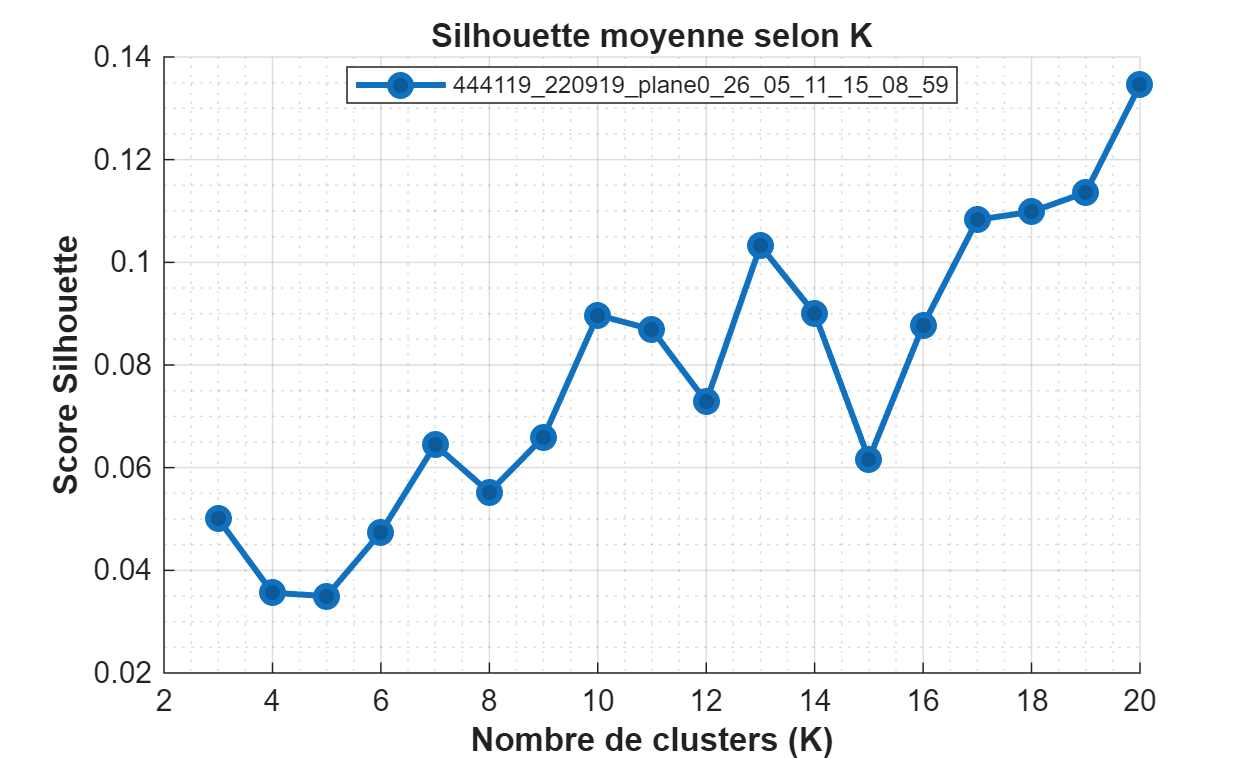


%% 7. GRAPHIQUES : Silhouette et Score Global vs K (TRIÉS PAR K CROISSANT)
figure('Name', 'Analyse des métriques par K', 'Color', 'w', 'Position', [100 100 1200 600]);

% --- TRI DES DONNÉES PAR K CROISSANT ---
sessionFields = fieldnames(SessionsData);
colors = lines(length(sessionFields));

% --- GRAPHIQUE 1 : Silhouette moyenne en fonction de K ---
% subplot(2, 2, 1);
figure
hold on;
for s = 1:length(sessionFields)
    sess = SessionsData.(sessionFields{s});
    if length(sess.K) >= 2
        % TRI PAR K CROISSANT
        [K_sorted, idx_sort] = sort(sess.K);
        Silh_sorted = sess.Silh(idx_sort);
        
        plot(K_sorted, Silh_sorted, '-o', 'Color', colors(s,:), 'LineWidth', 2.5, ...
            'MarkerSize', 7, 'MarkerFaceColor', colors(s,:)*0.8, ...
            'DisplayName', sess.OriginalName, 'LineWidth', 2);
    end
end
xlabel('Nombre de clusters (K)', 'FontWeight', 'bold');
ylabel('Score Silhouette', 'FontWeight', 'bold');
title('Silhouette moyenne selon K');
grid on; grid minor;
legend('Location', 'best', 'Interpreter', 'none', 'FontSize', 8);
% xlim([min_K-1, max_K+1]); % Adaptation automatique des limites
hold off;
nom_graph = fullfile(dossier_mere, 'silhouette.png');
saveas(gcf, nom_graph);

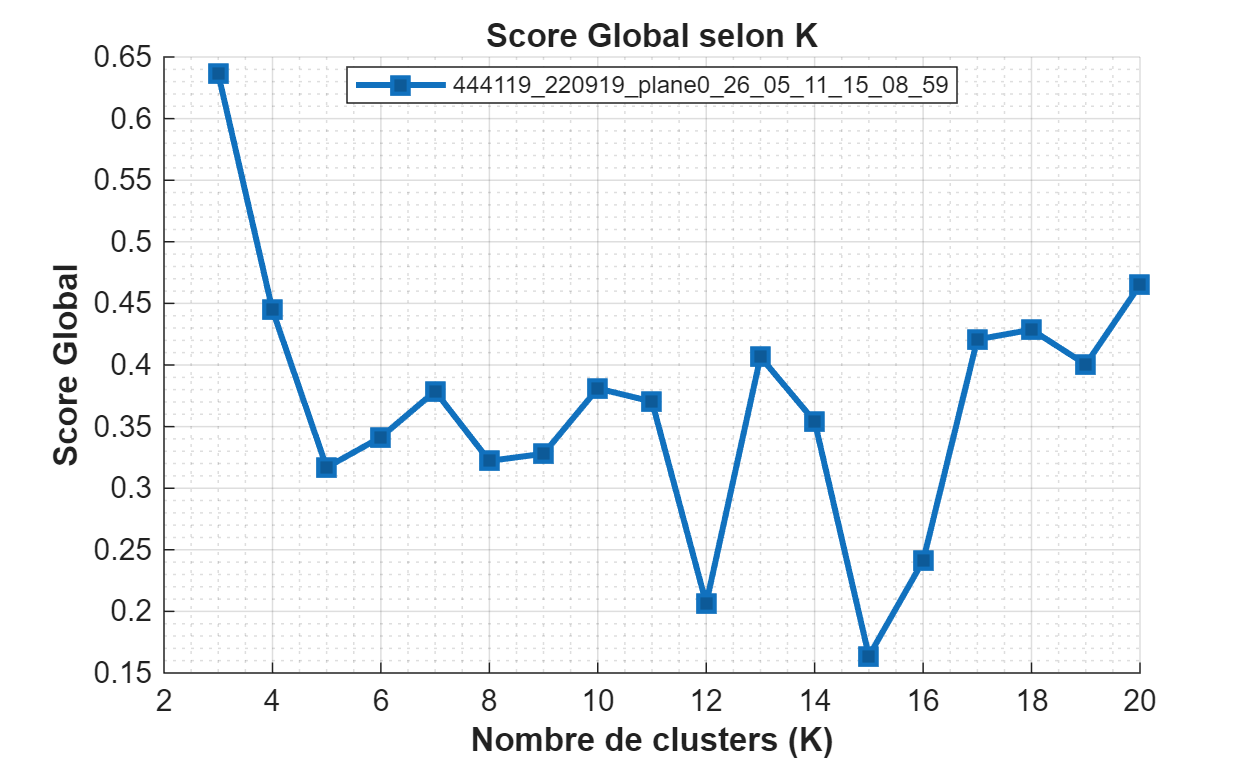


% --- GRAPHIQUE 2 : Score Global en fonction de K ---
figure
hold on;
for s = 1:length(sessionFields)
    sess = SessionsData.(sessionFields{s});
    if isfield(sess, 'Scores') && length(sess.K) >= 2
        % TRI PAR K CROISSANT
        [K_sorted, idx_sort] = sort(sess.K);
        Scores_sorted = sess.Scores(idx_sort);
        
        plot(K_sorted, Scores_sorted, '-s', 'Color', colors(s,:), 'LineWidth', 2.5, ...
            'MarkerSize', 7, 'MarkerFaceColor', colors(s,:)*0.8, ...
            'DisplayName', sess.OriginalName, 'LineWidth', 2);
    end
end
xlabel('Nombre de clusters (K)', 'FontWeight', 'bold');
ylabel('Score Global', 'FontWeight', 'bold');
title('Score Global selon K');
grid on; grid minor;
legend('Location', 'best', 'Interpreter', 'none', 'FontSize', 8);
hold off;
nom_graph = fullfile(dossier_mere, 'Score_global_K.png');
saveas(gcf, nom_graph);

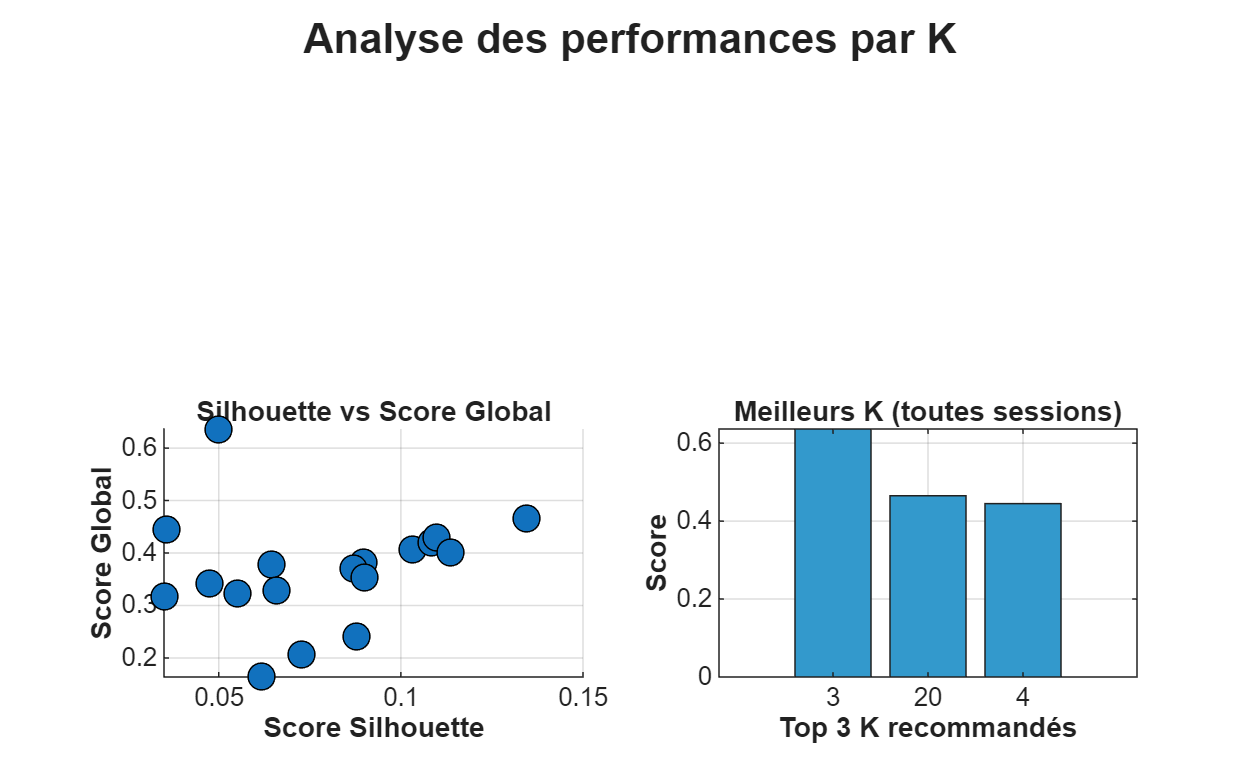



% % --- GRAPHIQUE 2 : Score Global en fonction de K ---
% subplot(2, 2, 2);
% hold on;
% for s = 1:length(sessionFields)
%     sess = SessionsData.(sessionFields{s});
%     if isfield(sess, 'Scores') && length(sess.K) >= 2
%         plot(sess.K, sess.Scores, '-s', 'Color', colors(s,:), 'LineWidth', 2, ...
%             'MarkerSize', 6, 'MarkerFaceColor', colors(s,:)*0.7, 'DisplayName', sess.OriginalName);
%     end
% end
% xlabel('Nombre de clusters (K)', 'FontWeight', 'bold');
% ylabel('Score Global', 'FontWeight', 'bold');
% title('Score Global selon K');
% grid on;
% legend('Location', 'best', 'Interpreter', 'none');
% hold off;

% --- GRAPHIQUE 3 : Silhouette vs Score Global (scatter) ---
subplot(2, 2, 3);
hold on;
all_silh = [];
all_scores = [];
all_labels = {};
for s = 1:length(sessionFields)
    sess = SessionsData.(sessionFields{s});
    if length(sess.K) >= 2
        all_silh = [all_silh, sess.Silh];
        all_scores = [all_scores, sess.Scores];
        all_labels = [all_labels, repmat({sess.OriginalName}, 1, length(sess.Silh))];
    end
end

scatter(all_silh, all_scores, 80, 'filled', 'MarkerEdgeColor', 'k');
xlabel('Score Silhouette', 'FontWeight', 'bold');
ylabel('Score Global', 'FontWeight', 'bold');
title('Silhouette vs Score Global');
grid on;
hold off;

% --- GRAPHIQUE 4 : Top 3 K recommandés ---
subplot(2, 2, 4);
top3_k = [];
top3_scores = [];
for s = 1:length(sessionFields)
    sess = SessionsData.(sessionFields{s});
    if length(sess.K) >= 2 && isfield(sess, 'Scores')
        [~, sortIdx] = sort(sess.Scores, 'descend');
        top3_k = [top3_k, sess.K(sortIdx(1:min(3, end)))];
        top3_scores = [top3_scores, sess.Scores(sortIdx(1:min(3, end)))];
    end
end
bar(1:length(top3_k), top3_scores, 'FaceColor', [0.2 0.6 0.8]);
xticks(1:length(top3_k));
xticklabels(arrayfun(@num2str, top3_k, 'UniformOutput', false));
xlabel('Top 3 K recommandés', 'FontWeight', 'bold');
ylabel('Score', 'FontWeight', 'bold');
title('Meilleurs K (toutes sessions)');
grid on;

sgtitle('Analyse des performances par K', 'FontSize', 14, 'FontWeight', 'bold');

% Sauvegarde automatique du graphique
nom_graph = fullfile(dossier_mere, 'Analyse_Performance_K.png');
saveas(gcf, nom_graph);

fprintf('Graphique sauvegardé : %s\n', nom_graph);

Graphique sauvegardé : E:\Data\Aurelie\analysis\Mai2026\nocues\assembly\444119_220919_plane0_26_05_11_15_08_59\Analyse_Performance_K.png



% Fonction de normalisation
function norm_val = normalize_metric(val_array, direction)
    min_v = min(val_array); max_v = max(val_array);
    if max_v == min_v, norm_val = ones(size(val_array)); return; end
    if strcmp(direction, 'maximize')
        norm_val = (val_array - min_v) ./ (max_v - min_v);
    elseif strcmp(direction, 'minimize')
        norm_val = (max_v - val_array) ./ (max_v - min_v);
    end
end
